# Cassini-Huygens Spacecraft

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

cassini = readtable("../data/cassini-planets.xlsx", "Sheet", "cassini", "TextType", "string");
planets = readtable("../data/cassini-planets.xlsx", "Sheet", "planets", "TextType", "string");

## Task 2

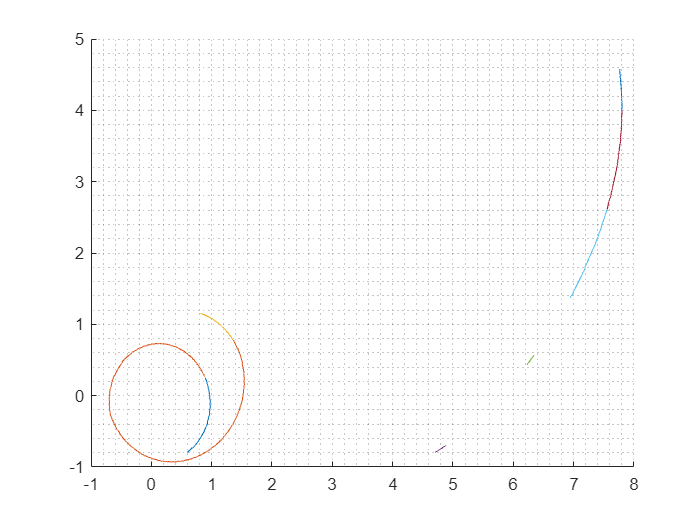

hold on
grid minor
for k = min(cassini.yr):max(cassini.yr)
    plot(cassini.x(cassini.yr==k), cassini.y(cassini.yr==k))
end
hold off

## Task 3

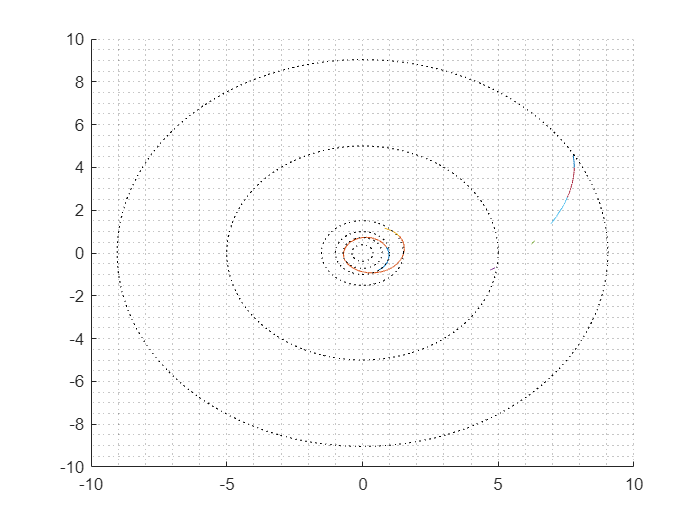

theta = linspace(0, 2*pi);
hold on
for k = 1:6
    plot(planets.Radius(k)*cos(theta), planets.Radius(k)*sin(theta), "k:")
end
hold off

## Task 4

d = round(sqrt(cassini.x.^2 + cassini.y.^2 + cassini.z.^2), 2);
t = zeros(length(planets.Radius), 1);
for k = 1:length(planets.Radius)
    t(k) = nnz(d == planets.Radius(k));
end
planets.Days = t

planets = 8×3 table
      Name       Radius    Days
    _________    ______    ____

    "Mercury"     0.39       0 
    "Venus"       0.72       6 
    "Earth"          1      17 
    "Mars"        1.51       8 
    "Jupiter"        5       0 
    "Saturn"      9.04       2 
    "Uranus"     19.18       0 
    "Neptune"    30.06       0 
